Now reading \\client\c$\Users\alexc\Documents\rats\testrats\0testrat2.jpg


Now reading \\client\c$\Users\alexc\Documents\rats\testrats\0testrat3.jpg


Now reading \\client\c$\Users\alexc\Documents\rats\testrats\0testrat5.jpg


Now reading \\client\c$\Users\alexc\Documents\rats\testrats\0testrat6.jpg


Now reading \\client\c$\Users\alexc\Documents\rats\testrats\1testrat1.jpg


Now reading \\client\c$\Users\alexc\Documents\rats\testrats\1testrat4.jpg


Now reading \\client\c$\Users\alexc\Documents\rats\testrats\2testrat7.jpg


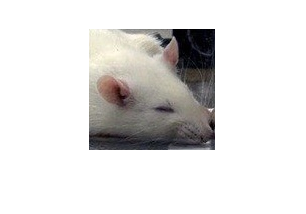

myFolder = '\\client\c$\Users\alexc\Documents\rats\testrats';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
testrats = dir(filePattern);
for k = 1:length(testrats)
  baseFileName = testrats(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  imageArray = imread(fullFileName);
  imshow(imageArray);  % Display image.
  drawnow; % Force display to update immediately.
end

save testrats;